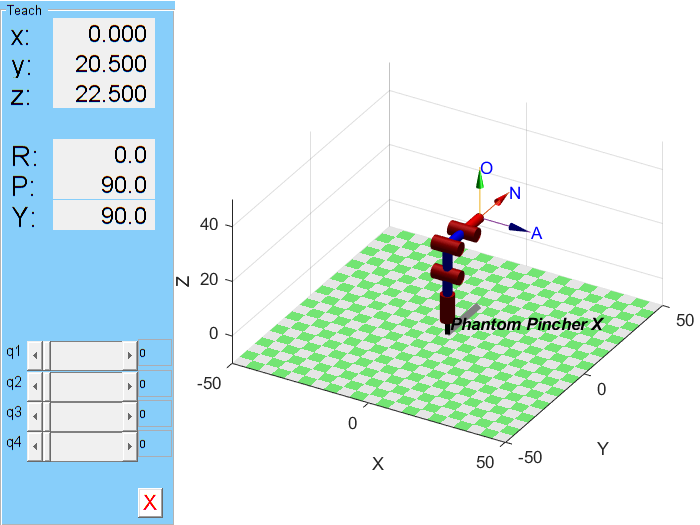

clear; clc; close all;
syms q1 q2 q3 q4;

% Definición de los parámetros DH
l1 = 12; l2 = 10.5; l3 = 10.5; l4 = 10;

% Matrices de transformación homogénea (DH)
mth01 = trotz(q1) * transl(0, 0, l1) * trotx(pi/2);
mth12 = trotz(q2) * transl(l2, 0, 0);
mth23 = trotz(q3) * transl(l3, 0, 0) * trotx(pi/2);
mth34 = trotz(q4) * transl(l4, 0, 0);

% Transformaciones acumuladas
mth02 = mth01 * mth12;
mth03 = mth02 * mth23;
mth04 = mth03 * mth34;

% Definición del robot en MATLAB
L1 = Revolute('d', l1, 'a', 0, 'alpha', pi/2, 'offset', pi/2, 'qlim', [0 2*pi]);
L2 = Revolute('d', 0, 'a', l2, 'alpha', 0, 'offset', pi/2, 'qlim', [0 2*pi]);
L3 = Revolute('d', 0, 'a', l3, 'alpha', 0, 'offset', -pi/2, 'qlim', [0 2*pi]);
L4 = Revolute('d', 0, 'a', l4, 'alpha', 0, 'offset', 0, 'qlim', [0 2*pi]);

robot = SerialLink([L1 L2 L3 L4], 'name', 'Phantom Pincher X');
clf;
figure(1);
ws = [-50 50 -50 50 -10 50]; % Ajuste del espacio de trabajo para mejorar la visualización
robot.plot([0 0 0 0], 'workspace', ws, 'noa', 'view', [30 30]); % Configuración inicial
hold on;
robot.teach(); % Modo de enseñanza para mover el robot manualmente

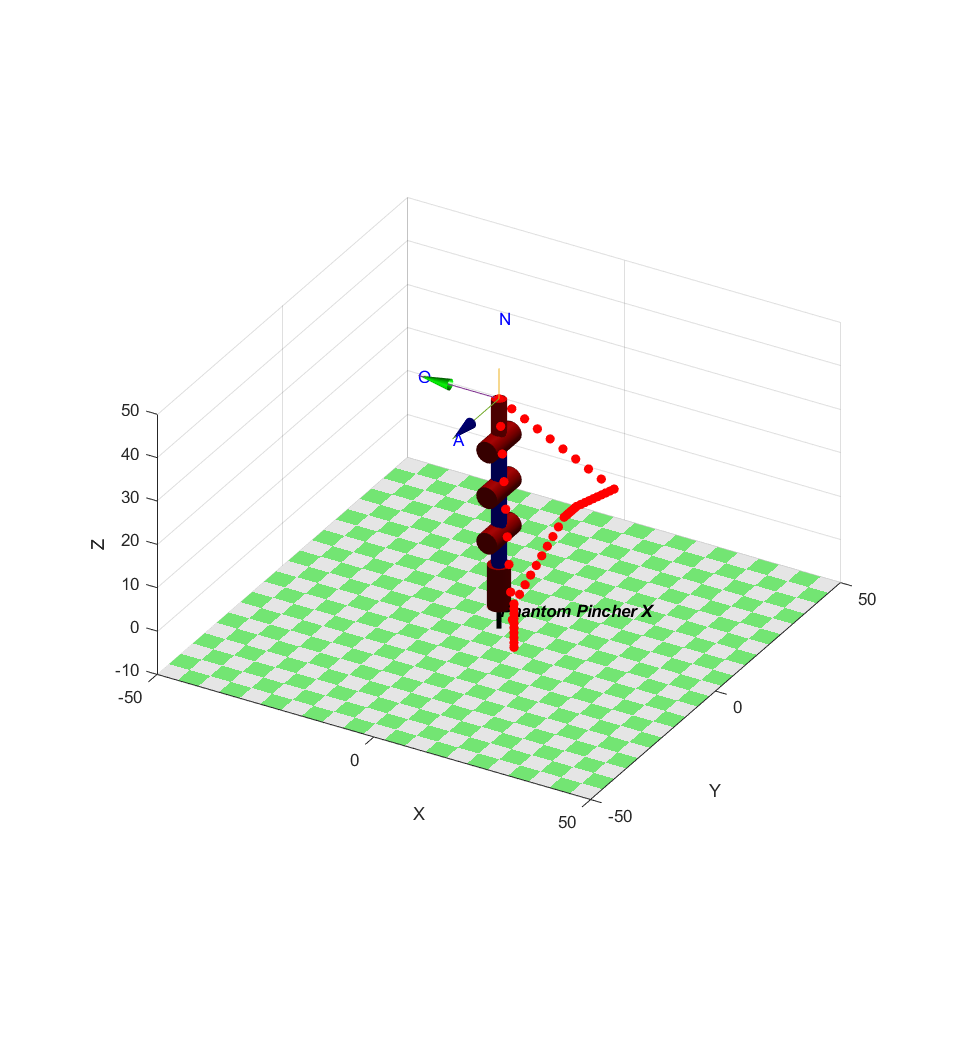

% Definición de waypoints
puntos = [
    0, 0, 43, 90;
    15, 20, 16.5, 0;
    15, 5, 20, -45;
    15, 0, 20, -45;
    15, -20, 10, -90;
    15, -20, 0, -90;
    0, 0, 43, 90;
];
numSteps=10;
waypoints=interpolateSphericalTrajectory(puntos, numSteps);

% Simulación del robot
plot3(waypoints(:,1), waypoints(:,2), waypoints(:,3), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r');

num_points = size(waypoints, 1);
q_tom = zeros(num_points, 5); % Inicializar matriz para almacenar posiciones

for i = 1:num_points
    q = invkin(waypoints(i,1), waypoints(i,2), waypoints(i,3), l1, l2, l3, l4, waypoints(i,4));
    q_phan = round((q + [150, 156, 63, 151]) / 0.29297);
    q_phan = min(max(q_phan, 0), 1023); % Evitar valores fuera de rango
    q_tom(i,:) = [q_phan, 270]; % Almacenar posición con el gripper cerrado
    robot.plot(deg2rad(q), 'workspace',ws, 'noa', 'view', [30 30]);
    pause(0.1);
end
hold off;

clear ros2node
clear msg
ros2node = ros2node("matlab_node"); % Crear un nodo de ROS 2 en MATLAB
pub = ros2publisher(ros2node, "/goal_joint_pos", "std_msgs/UInt16MultiArray");
msg = ros2message(pub); % Crear mensaje vacío
pause(5);
msg.data = uint16([512 512 512 512 512]);
send(pub,msg);
pause(5);
msg.data = uint16([q_tom(1,1:4) 512]);
send(pub,msg);
pause(5);
msg.data = uint16([q_tom(1,:)]);
send(pub,msg);
pause(5);
for i = 1:size(q_tom, 1)
    msg.data = uint16(q_tom(i, :)); % Convertir a Int16 par0 ROS 2
    send(pub, msg); % Enviar comando al robot
    pause(0.5); % Esperar un poco para sincronización
end
msg.data = uint16([q_tom(num_points, 1:4) 512]);
send(pub,msg);
pause(2);
msg.data = uint16([q_tom(num_points-1, 1:4) 512]);
send(pub,msg);
pause(2);
msg.data = uint16([512 512 512 512 512]);
send(pub,msg);
disp("Comando enviado al Pincher Phantom X.");

Comando enviado al Pincher Phantom X.


function q_sim = invkin(x, y, z, l1, l2, l3, l4, phi)
    % Ángulo base
    q1 = rad2deg(atan2(y, x) - pi/2);

    % Posición del efector sin la herramienta
    pwx = sqrt(x^2 + y^2) - l4 * cosd(phi);  
    pwz = z - l4 * sind(phi) - l1;  

    % Distancia al punto objetivo
    r = sqrt(pwx^2 + pwz^2);

    % Ángulo q3 (Ley de cosenos)
    D = abs(r^2 - l2^2 - l3^2) / (2 * l2 * l3);
    q3 = rad2deg(atan2(-sqrt(abs(1 - D^2)), D) + pi/2);  

    % Ángulo q2 (Ley de senos y cosenos)
    alpha = atan2(pwz, pwx);
    beta = atan2(l3 * sind(q3 - 90), l2 + l3 * cosd(q3 - 90));
    q2 = rad2deg(alpha - beta) - 90;

    % Ángulo de la herramienta
    q4 = phi - q2 - q3;

    % Retornar ángulos articulares
    q_sim = [q1, q2, q3, q4];
end
function trajectory = interpolateSphericalTrajectory(waypoints, numSteps)
    % waypoints: Matriz de waypoints [x, y, z, phi]
    % numSteps: Número de pasos de interpolación entre waypoints
    % trajectory: Matriz de la trayectoria interpolada [x, y, z, phi]

    % Inicializar la trayectoria con el primer waypoint
    trajectory = waypoints(1, :);

    % Iterar sobre los waypoints
    for i = 1:size(waypoints, 1) - 1
        % Obtener waypoint actual y siguiente
        start = waypoints(i, :);
        goal = waypoints(i + 1, :);

        % Interpolar posición (x, y, z) linealmente
        x_interp = linspace(start(1), goal(1), numSteps);
        y_interp = linspace(start(2), goal(2), numSteps);
        z_interp = linspace(start(3), goal(3), numSteps);

        % Interpolar ángulo phi usando SLERP (interpolación esférica)
        phi_start = deg2rad(start(4));
        phi_goal = deg2rad(goal(4));
        t = linspace(0, 1, numSteps);
        phi_interp = phi_start + t .* (phi_goal - phi_start);

        % Convertir de nuevo a grados
        phi_interp = rad2deg(phi_interp);

        % Combinar resultados
        segment = [x_interp', y_interp', z_interp', phi_interp'];
        
        % Evitar duplicar el waypoint inicial
        if i > 1
            trajectory = [trajectory; segment];
        else
            trajectory = [trajectory; segment(2:end, :)];
        end
    end
end